## **SIMULATION PHYSIQUE D'UN CORONOGRAPHE**

**Les grandeurs pris en compte sont celles données sur le notion, les seules que j'occulte à raison sont le diamètre de L1 et L2 (vignettage possible ?)**

`grandeurs d'échantillonnage pour FFT`

N = 2^11;% nombre d'échantillonnage
S = 0.006; %DEMI taille du support de la pupille en metre
N2=2*N;% taille des matrices après  0 pading
xN = 1:N;
yN = xN;


`Grandeurs physiques du probleme et intensités d'affichage.`

Eps_I = 3.5*10^-5/100 ; %rapport d'intensité compagnon/étoile.
Eps_U = Eps_I.^(1/2)  

Eps_U = 5.9161e-04

lambda = 630E-9; %en metre

Fobj = 0.18;% focale objectif en metres
FL2 = 0.075;%
FL3 = 0.08;%


R_cache = 2.5*10^-3; %rayon du cache opaque en mètres
R_Lyot = 0.0006; % rayon du diaphragme de Lyot en metres
P = 0.0005; % rayon du diaphragme de Lobj d'entrée en mètres

dB_Plan3 = -40 ;
dB_Plan3P = -40 ; 


 `PLAN 0 pupille`

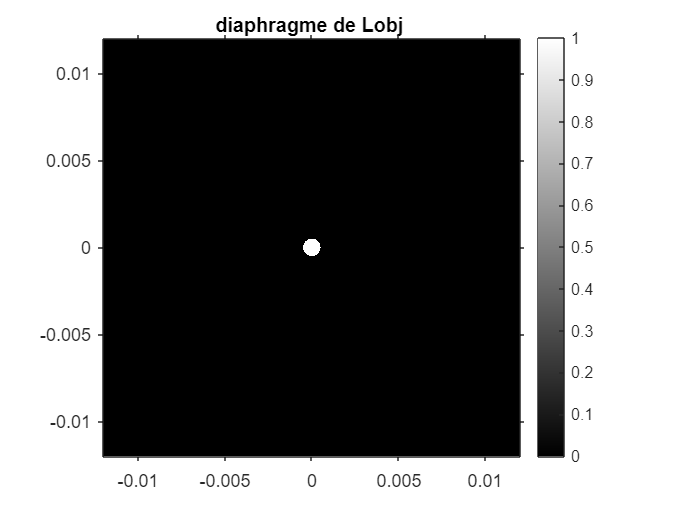

%---Dimensions du Plan0-----
dx0=2*S/N;% pas d'échantillonnage dans le plan0
df0 = 1/(dx0*N);% pas d'échantillonnage fréquentiel du plan0 en m-1;
%---------------------------

[PLAN0,x,y]=PorteDisqueR1(N2,2*S,P); % on utilise N2 pour le resample ensuite

AffImGris(x,y,PLAN0)
title("diaphragme de Lobj ")

`PLAN 1 tache d'airy et compagnon avant masque(s)`

%---Dimensions du Plan1-----
dx1 = df0 * lambda * Fobj    ;  %taille de chaque pixel dans le plan 1
S1 = dx1*N/2 ; %surface d'étude dans le plan 1
xm1 = dx1*(-N/2:N/2-1); %tableau d'échantillonnage distance dans le plan1
ym1 = xm1;
PhiAiry = 1.22*lambda*Fobj/P; %diametre tache d'airy dans le plan 1 CEST BON
df1 = 1/(dx1*N) ; % pas d'échantillonnage fréquentiel du plan0 en m-1;
%---------------------------

M2=ifftshift(PLAN0); % shiftage dans le plan objet pour anéantir la varicelle 
AiryPdouble=fftshift(fft2(M2)); % Tf de la pupille/ tache d'airy

AiryP=resample(AiryPdouble,N2);

Pos_Comp_Pix =[N/4,-N/4]; % position du compagnon /!\ n'est pas défini de manière physique ?
Dist_Comp_Phys1 = (sum(Pos_Comp_Pix.^2)^(1/2))*dx1 %distance entre l'étoile et le compagnon.

Dist_Comp_Phys1 = 0.0068

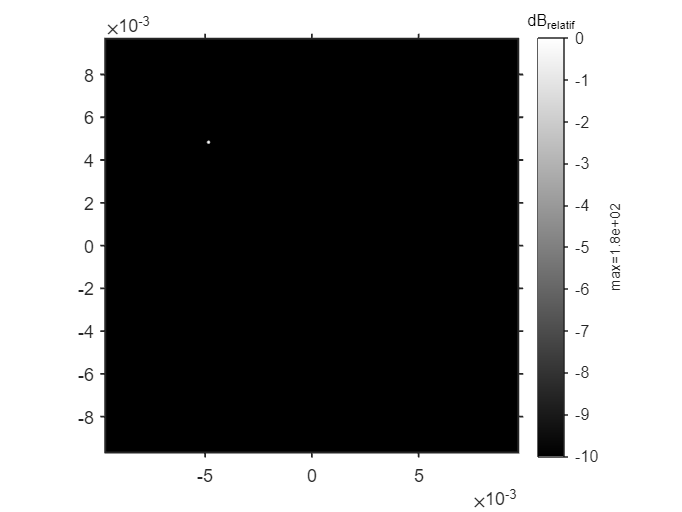


M_comp = circshiftzeropad(AiryP,Pos_Comp_Pix(1),Pos_Comp_Pix(2)); %création de la matrice compagnon à partir de la tache d'airy de letoile
M_comp = Eps_U*1i*M_comp; %Il faut multiplier par i pour faire comme si l'étoile et la planete étaient incohérentes Sinon il interfère avec l'étoile ce qui n'a pas de sens
%/!\ pas sur pour la ligne du dessus, à demander à Arno dubois

AiryP_Comp = AiryP+M_comp;
figure
VisuIdB(xm1,ym1,M_comp,-10)

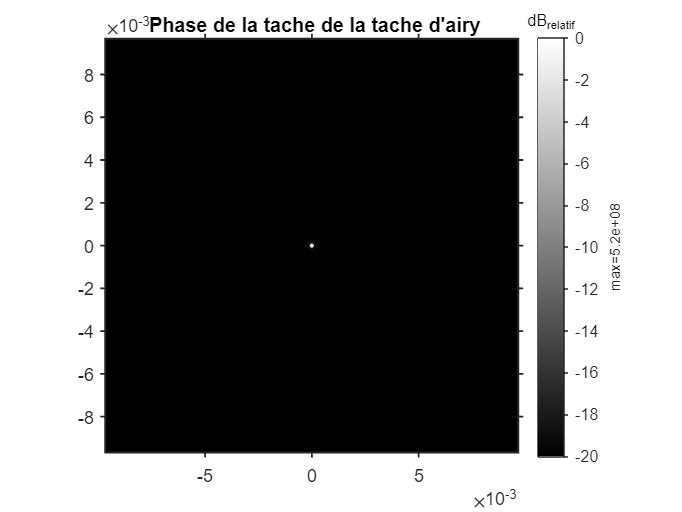

VisuIdB(xm1,ym1,AiryP_Comp,-20) 
title(" Phase de la tache de la tache d'airy") %après resample.

`PLAN 1bis Cache physique et masque(s) de phase`

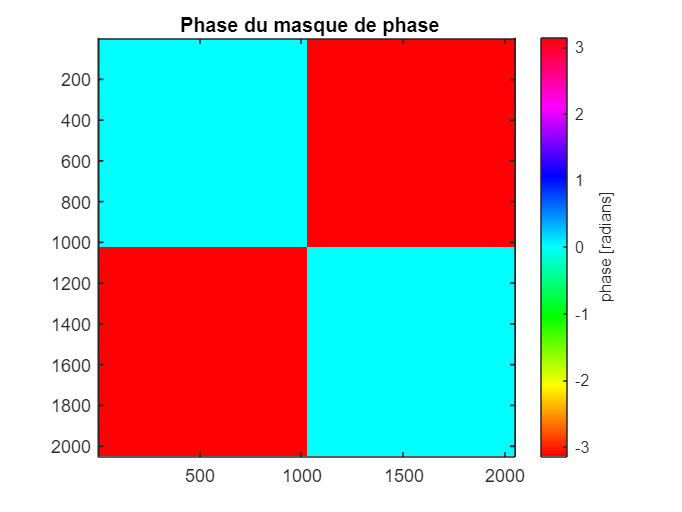

[mask] = masque_quadrature_pascentre_pasouf(N,0,0,1.0000,1);

figure
VisuPh(mask)
title(" Phase du masque de phase")

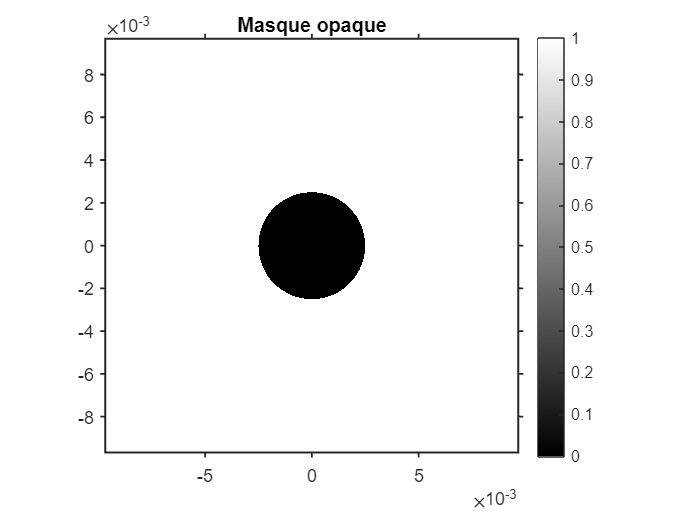

[Mcache,~,~]=Cache_physique(N,S1,R_cache);

figure
AffImGris(xm1,ym1,Mcache) 
title("Masque opaque")

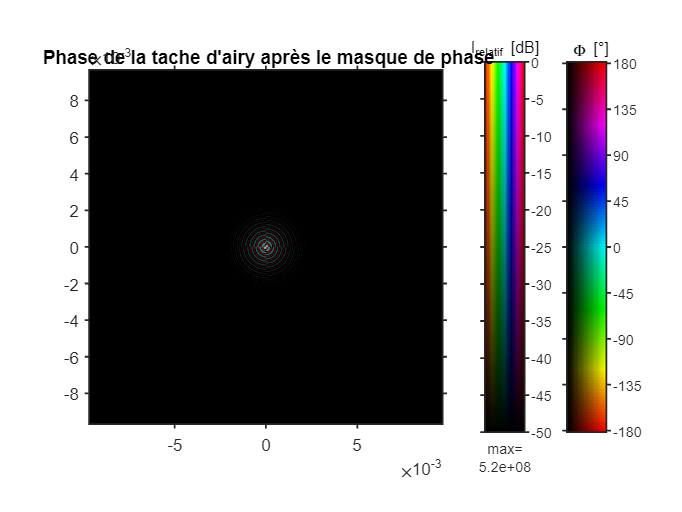


PLAN1 = mask .* AiryP_Comp;
PLAN1P =Mcache.* AiryP_Comp;

figure
VisuIdBPh(xm1,ym1,PLAN1,-50)
title(" Phase de la tache d'airy après le masque de phase")

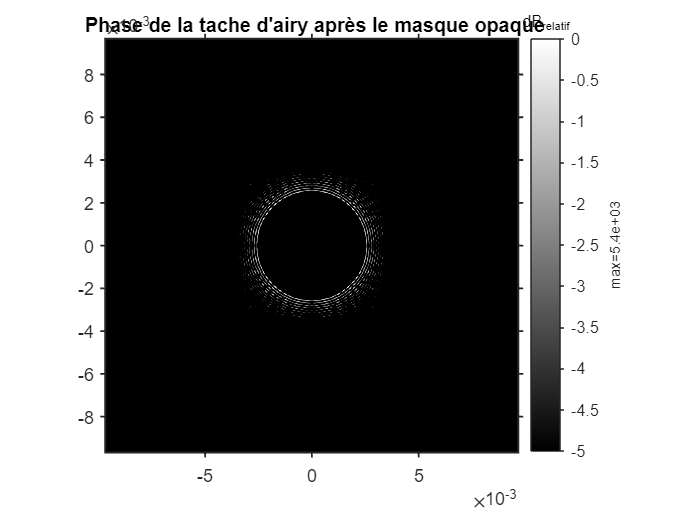


figure
VisuIdB(xm1,ym1,PLAN1P,-5)
title(" Phase de la tache d'airy après le masque opaque")

`PLAN 2 avant diaphragme de LYOT`

%---Dimensions du Plan2-----
z1 = FL2 + Fobj ;
z2 = 1/((Fobj^-1) - (z1^-1)) ;
z2*(z1-FL2)/z1 ;
dx2 = df1 * lambda * z2*(z1-FL2)/z1;  %taille de chaque pixel dans le plan 2
S2 = dx2*N/2 %dimension physique de l'image étudié dans les plan 2

S2 = 0.0144

xm2 = dx2*(-N/2:N/2-1); %tableau d'échantillonnage distance dans le plan 2
ym2 = xm2;
df2 = 1/(dx2*N)

df2 = 34.7222

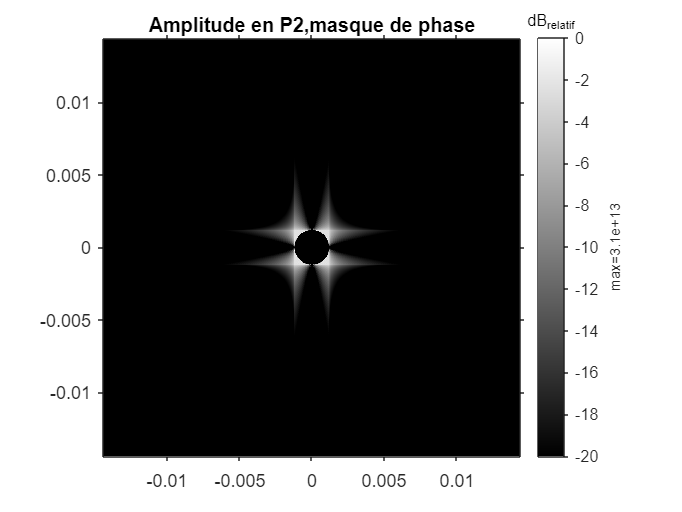

%---------------------------

M2=ifftshift(PLAN1);
M2P=ifftshift(PLAN1P); 
PLAN2=fftshift(fft2(M2));% Image sur le plan avant le diaphragme de Lyot, masque de phase
PLAN2P=fftshift(fft2(M2P)); % Image sur le plan avant le diaphragme de Lyot, masque opaque

figure
VisuIdB(xm2,ym2,PLAN2,-20)
title("Amplitude en P2,masque de phase")

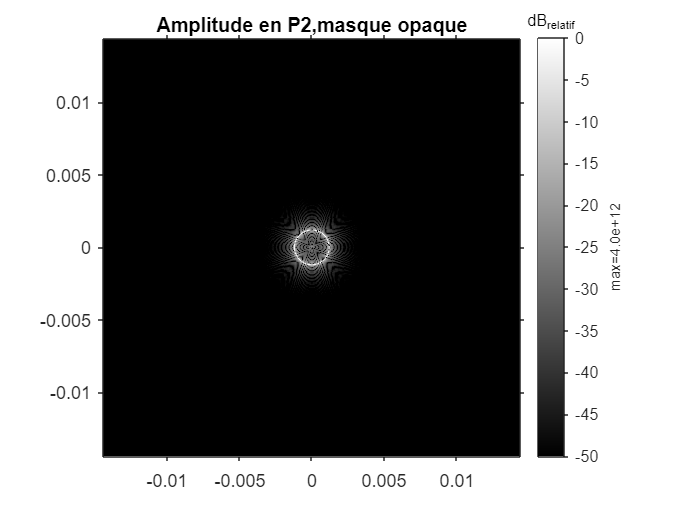


VisuIdB(xm2,ym2,PLAN2P,-50)
title("Amplitude en P2,masque opaque")

`PLAN 2bis après diaphragme de Lyot`

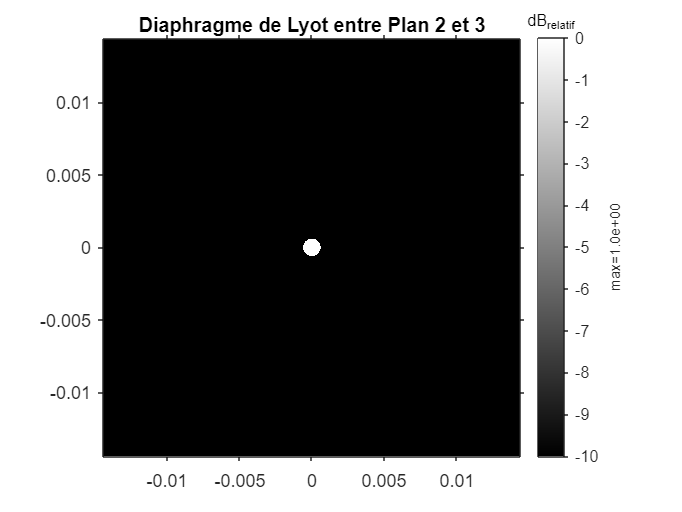

[M_Lyot,~,~]=PorteDisqueR1(N,S2,R_Lyot);
VisuIdB(xm2,ym2,M_Lyot,-10)
title("Diaphragme de Lyot entre Plan 2 et 3")

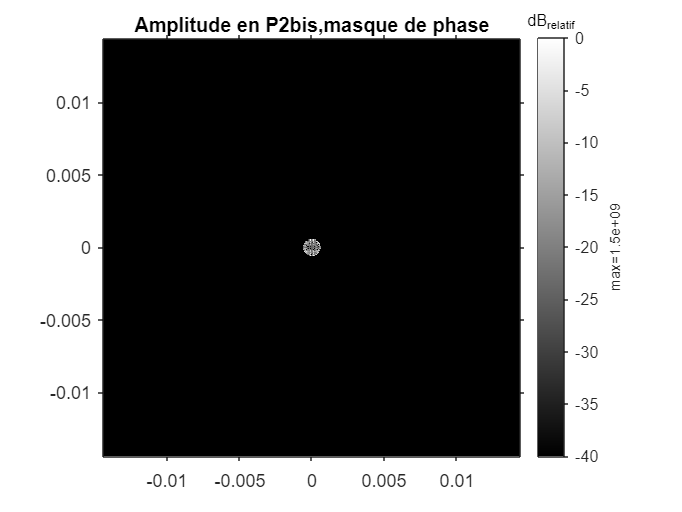


PLAN2bis = PLAN2 .* M_Lyot;   % Plan après le diaphragme de Lyot, masque de phase
PLAN2bisP = PLAN2P .* M_Lyot; % Plan après le diaphragme de Lyot, masque opaque
figure
VisuIdB(xm2,ym2,PLAN2bis,-40)
title("Amplitude en P2bis,masque de phase")

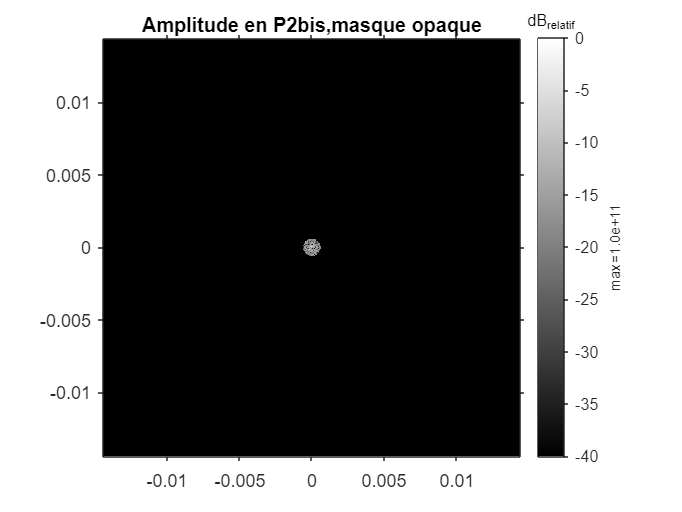

VisuIdB(xm2,ym2,PLAN2bisP,-40)

title("Amplitude en P2bis,masque opaque")

`PLAN 3 plan image`

%---Dimensions du Plan3-----
dx3 = df2 * lambda * FL3;  %taille de chaque pixel dans le plan 1
S3 = dx3*N/2 %dimension physique de l'image étudié dans les plan 2 et 3

S3 = 0.0018

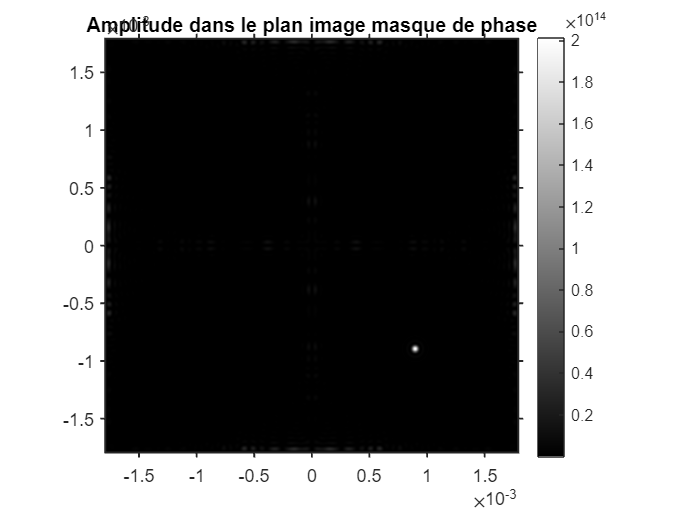

xm3 = dx3*(-N/2:N/2-1); %tableau d'échantillonnage distance dans le plan1
ym3 = xm3;
%---------------------------

M2=ifftshift(PLAN2bis);
M2P=ifftshift(PLAN2bisP);
PLAN3_U=fftshift(fft2(M2));
PLAN3_I=abs(PLAN3_U).^2 ;%passage en intensité
PLAN3P_U=fftshift(fft2(M2P));
PLAN3P_I=abs(PLAN3P_U).^2; %passage en intensité

% % % % % % %REGARDER LINTENSITE CA REVIENT JUSTE A DOUBLER LES DB DONC OSEEEEEF
% % % % % % %IL SUFFIT JUSTE DE SE SOUVENIR OU DOIT ETRE LE COMPAGNON ET DESCENDRE LE
% % % % % % %SEUIL de l'affichage de VisuIdB JUSQUA QUON LE VOIT OU QU ON APERCOIVE LES INTERFERENCE DE LETOILE 
% % % % % % %CELUI QUI APPARAIT EN PREMIER GAGNE

figure
AffImGris(xm3,ym3,abs((PLAN3_U).^2))
title("Amplitude dans le plan image masque de phase")

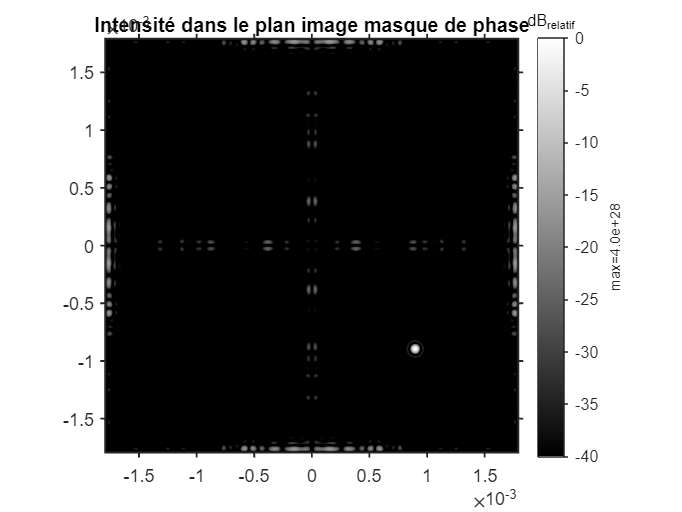


figure
VisuIdB(xm3,ym3,PLAN3_I,-40)
title("Intensité dans le plan image masque de phase")

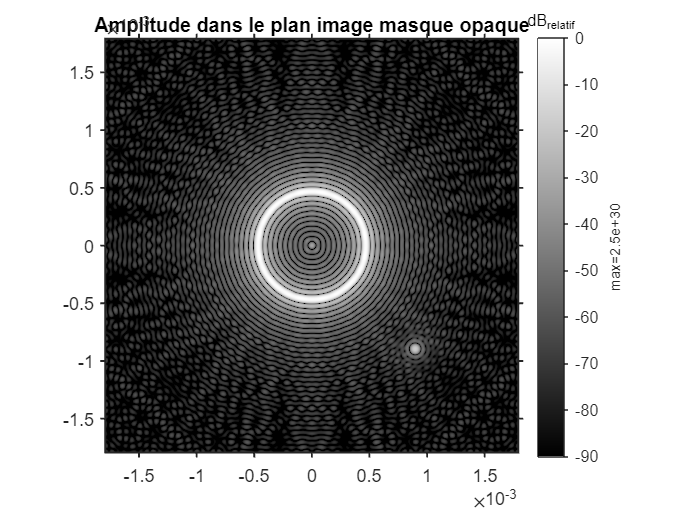

R_pix = (R_cache/S1*N/2);
Dist_comp = sum(Pos_Comp_Pix.^2)^(1/2);
if R_pix >= Dist_comp*8/9
  disp("LE COMPAGNON EST MASQUE PAR LE MASQUE GROBOUF") 
end

figure
VisuIdB(xm3,ym3,abs((PLAN3P_U).^2),-90)
title("Amplitude dans le plan image masque opaque")




% figure
% VisuIdB(xm3,ym3,PLAN3P_I,-20)
% title("Intensité dans le plan image masque opaque")
Dist_Comp_Phys3 = Dist_Comp_Phys1*FL3/FL2

Dist_Comp_Phys3 = 0.0073

Fonctions

function [M,x,y]=PorteDisqueR1(N,S,P)
% PorteDisqueR1 - calcule l'éch. fonc. porte/disqR1 dans [-S,+S[×[-S,+S[
% USAGE: [M,x,y]=PorteDisqueR1(N,S)
% N: scalaire entier positif PAIR, la taille de l'échantillonnage à créer
% S: scalaire réel positif > 1, la taille du carré dans lequel est représentée
% la fonction porte sur un disque
% M: matrice réelle de taille N×N contenant l'échantillonnage de la fonction
% porte, disque centré de manière à ce que
% ifftshift(M) place le centre du disque en (1,1).
% x,y: vecteurs réels décrivant l'échantillonnage des x et y.
% AffImGris(x,y,M) peut représenter le résultat.
if N<2 || mod(N,2)~=0
 error('N n''est pas un nombre entier PAIR strictement positif')
end
pas=2*S/N;
x=pas*(-N/2:N/2-1);
% on aurait aussi pu écrire «x=linspace(-S,S,N+1);x(N+1)=[];»
y=x;
[X,Y]=meshgrid(x,y);
M=double(X.^2+Y.^2<=P.^2);
end

function  [mask] = masque_quadrature(N)
%r rayon du mask de phase
%x,y échantillonnage de l'espace
mask = ones(N/2,N/2);
mask =[mask -mask ; -mask mask];
end

function [mask] = masque_quadrature_pascentre_pasouf(N,g,h,phi,amp)
%phi entre 0 et 2  
mask_hg = ones(N/2+h,N/2-g);
mask_hd = ones(N/2+h,N/2+g);
mask_bg = ones(N/2-h,N/2-g);
mask_bd = ones(N/2-h,N/2+g);
mask = [mask_hg amp*exp(i*phi*pi).*mask_hd ; amp*exp(i*phi*pi).*mask_bg mask_bd]; %création du masque quatre quadrants

end

function M=compagnon_rond(N,S,rayon_comp,pos,Eps_U)
%Globalement une copie de la fonction porte disque du dessus

pas=2*S/N;
x=pas*(-N/2:N/2-1);
% on aurait aussi pu écrire «x=linspace(-S,S,N+1);x(N+1)=[];»
y=x;
[X,Y]=meshgrid(x,y);
M=Eps_U .* double((X-pos(1)*pas).^2+(Y-pos(2)*pas).^2<=(rayon_comp*pas).^2);
end

function Eout = circshiftzeropad(Ein,shifty,shiftx) %Permet de shifter Airy pour créer le compagnon
%function Eout = circshiftzeropad(Ein,shifty,shiftx)
%shifts and zeropads an array
Eout = circshift(Ein,[shifty shiftx]);
if shiftx <0 
Eout(:,(end+shiftx):end)= 0;
else
Eout(:,(1:shiftx))= 0;
end
if shifty <0 
Eout((end+shifty):end,:)= 0;
else
Eout((1:shifty),:)= 0;
end
end


function  [mask] = masque_quadrature2(N)
%r rayon du mask de phase
%x,y échantillonnage de l'espace
mask = ones(N/2,N/2);
mask =[mask -mask ; -mask mask];

for k=1:N
    for j=1:N
        if k==N/2+1

            mask(k,j)=1*i;
        end

        if j==(N/2)+1
            mask(k,j)=1*i;
        end
        
    end



end
end


function [M,x,y]=Cache_physique(N,S,P)

pas=2*S/N;
x=pas*(-N/2:N/2-1);
% on aurait aussi pu écrire «x=linspace(-S,S,N+1);x(N+1)=[];»
y=x;
[X,Y]=meshgrid(x,y);
M=double((X+1/2*pas).^2+(Y+pas*1/2).^2>=P.^2); %Le plus 1/2 est important car la tache d'airy, à cause du resample, est centré maintenant en (-1/2 , -1/2)
% la ligne du dessus rend le cache de diametre Pair.
end

function Ms=resample(M,N)
    Ms = zeros(N/2,N/2);   
    for i=1:N
        for j=1:N
            if mod(j,2) == 0 && mod(i,2) == 0
                Ms((i)/2,(j)/2)=M(i,j);
            end
        end
    end
end

function  [mask] = masque_damier(N)
    mask=ones(N,N);
    for i=1:N
        for j=1:N
            if mod(i+j,2)==0
                mask(i,j)=-1;
            end
        end
    end
end

function  [mask] = masquecolonne(N)
    mask=ones(N,N);
        for j=1:N
           for i=1:N
               if mod(i,2)==1
                   mask(i,j)=-1;
        end
    end
   end
end

function [mask] = croix(N)

    mask=ones(N,N);
    for i=2:N-1
        for j=2:N-1
            if i == N/2 
                mask(i-2:i+2,j)=0;
           
            end
            if j ==N/2 
                mask(i,j-2:j+2)=0;
              
            end
        end
    end
end

function  [mask] = masque_damieretendue(N,p)
    mask=ones(N,N);
    for i=1:2:N-1
        for j=1:2:N-1
            if mod(i+j,4)==0
                mask(i:i+1,j:j+1)=-1;
                
            end
        end
    end
end

function [M,x,y]=masque_cercle_concentrique(N,S,P)
k=1;
while k*P<N/2
    k=k+1;
end

pas=2*S/N;
x=pas*(-N/2:N/2-1);
% on aurait aussi pu écrire «x=linspace(-S,S,N+1);x(N+1)=[];»
y=x;
[X,Y]=meshgrid(x,y);
M=ones(N,N);
while k*P>0
    M=double((X-1/2).^2+(Y-1/2).^2<=(P*k).^2) *(-1)^k;
end
end

